# Code and data to reproduce figures from Cheynet et al. [1]

## Introduction

This script is designed to reproduce specific figures presented in the article by Cheynet et al. titled "A one-year comparison of new wind atlases over the North Sea" published in the Journal of Physics: Conference Series, Vol. 2362, No. 1, p. 012009, IOP Publishing, November 2022.

### Datasets Used

1. **BSH**: Data from the FINO1 offshore mast.

2. **ERA5**: Wind data covering the period from 1985 to 2015.

3. **NORA3**: Norwegian hindcast archive dataset with hourly resolution.

4. **NEWA**: New European Wind Atlas with 30-minute resolution.

### Data Variables

The variable are Matlab structures variables with the following fields

1. BSH: 

   - **time**: Time data

   - **U**: Profile of mean wind speed

   - **Dir**: Profile of mean wind direction

   - **Temp**: Profile of temperature

   - **P**: Profile of atmospheric pressure

   - **RH**: Profile of relative humidity

   - **zU**: Height for wind speed data

   - **zTemp**: Height for temperature data

   - **zDir**: Height for direction data

   - **zHum**: Height for humidity data

2. NORA3:

   - **U**: Profile of mean wind speed

   - **D**: Profile of mean wind direction

   - **T**: Profile of mean temperature

   - **T0**: Surface temperature

   - **P0**: Surface pressure

   - **time**: Time data

   - **zT**: Height for temperature data

   - **z**: Height for wind speed and direction data

3. NEWA:

   - **U**: Profile of mean wind speed

   - **D**: Profile of mean wind direction

   - **time**: Time data

   - **T**: Temperature at 100 m

4. ERA5:

   - **U**: Mean wind speed at 100 m

   - **D**: Mean wind direction at 100 m

   - **time**: Time from 1985 to 2015

### Abstract Summary

Cheynet et al. provide a comparison of the New European Wind Atlas (NEWA) and the Norwegian hindcast archive (NORA3) database in terms of modeling the long-term wind climatology. They focus on hourly mean wind speed and wind direction data from 2009 at the FINO1 platform in the North Sea.

The article compares the performances of NORA3 and NEWA using the mean wind speed, mean wind direction, and static atmospheric stability. NORA3 is found to slightly outperform NEWA in terms of bias, root-mean square error and Earth's mover distance. Both wind atlases show promise for improved offshore wind assessment in regions like the North Sea and Norwegian sea.

## Load the data

Load core datasets `BSH`, `NORA3`, and `NEWA` from the data file `data_Cheynet2022.mat`. These datasets represent various atmospheric characteristics captured or modeled for the FINO1 platform.

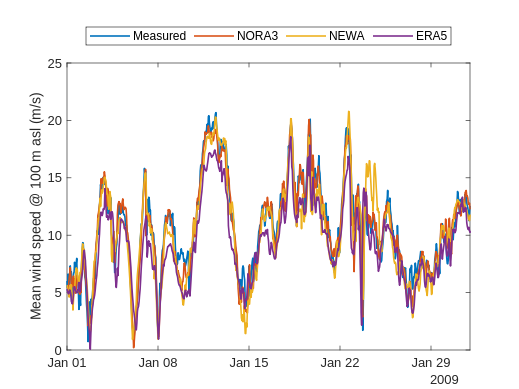

clearvars;close all;clc;
set(0, 'DefaultFigureRenderer', 'painters');
addpath('./functions');
load('./data/data_Cheynet2022.mat','BSH','NORA3','NEWA','ERA5');


figure
plot(BSH.time,BSH.U(end,:),...
    NORA3.time,NORA3.U(4,:),...
    NEWA.time,NEWA.U(4,:),'linewidth',1.2)
hold on
plot(ERA5.time,ERA5.U,'linewidth',1.2)
xlim([datetime(2009,1,1,0,0,0),datetime(2009,2,1,0,0,0)])
legend('Measured','NORA3','NEWA','ERA5','location','northoutside','Orientation','horizontal')
ylabel('Mean wind speed @ 100 m asl (m/s)')

## Compare temperature data at 101 m asl

Absolute air temperature T at 101 m asl on the FINO1 platform compared to the values computed  using NORA3 (left) and NEWA (right). Each dot represents one hour of  data, collected from 2009-01-01 to 2009-12-31.

Define `zTarget` as 101 meters, signifying the height at which temperature data is to be analyzed.

For the NEWA dataset, it's noted that temperature data is readily  available for a height of 100 m. For the purpose of this analysis, it's  presumed that temperature remains consistent between 100 m and 101 m.

Run `plotFig5(BSH,NORA3,NEWA,zTarget)`. This function  visualizes the temperature data at the defined height, contrasting the  in-situ measurements from FINO1 with the modeled data from NORA3 and  NEWA.

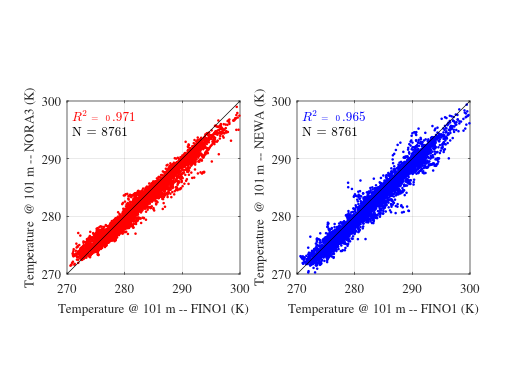

Temperature bias between BSH and NEWA: -0.862 
Temperature bias between BSH and NORA3: -0.579 


zTarget = 101; % in meters
% The temperature from NEWA is already at 100 m, which is assumed identical
% at 101 m
% We need to interpolate the temperature profile from NORA3 to the height
% of 101 m
[T_NORA3_100m] =plotFig5(BSH,NORA3,NEWA,zTarget);

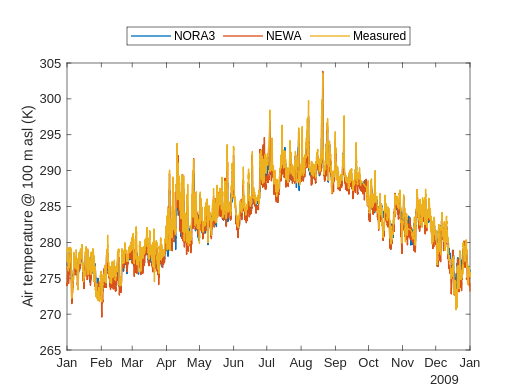



% Air temperature at 100 m
figure
plot(NORA3.time,T_NORA3_100m,...
    NEWA.time,NEWA.T,...
    BSH.time,BSH.Temp(end,:),'linewidth',1.0)
hold on
xlim([datetime(2009,1,1,0,0,0),datetime(2010,1,1,0,0,0)])
legend('NORA3','NEWA','Measured','location','northoutside','Orientation','horizontal')
ylabel('Air temperature @ 100 m asl (K)')

## Compare wind speed profiles at 50 m and 102 m asl

Hourly mean wind speed at 51 m (left panel) and 101 m (right panel)  estimated by NORA3 and NEWA compared to cup anemometer measurements from the FINO1 platform. Each dot represents one hour of data, collected  from 2009-01-01 to 2009-12-31.

Define `zTarget` as a two-element vector containing the  values [50,102]. This specifies the two heights at which the wind speed  data will be analyzed.

Execute `plotFig2(BSH,NORA3,NEWA,zTarget)`. This function  presents the wind speed data at the specified heights, juxtaposing the  in-situ wind speed measurements from the FINO1 platform's cup  anemometers with the modeled data from both NORA3 and NEWA.

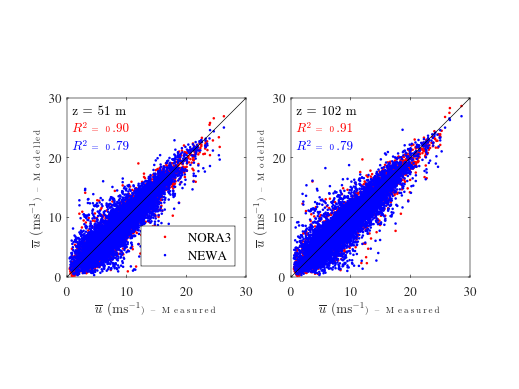

zTarget = [50,102];
plotFig2(BSH,NORA3,NEWA,zTarget);

## Compare pdf of wind speed at 100 m asl

Distribution of the mean wind speed at 100 m asl in 2009, measured on  the FINO1 platform, modeled by NORA3, NEWA and ERA5 for  the period 1985-2015. The solid black lines represent the least-square  fit of a Weibull distribution. The shape and scale parameters of this  distribution are denoted as *a* and *b*, respectively.

Define `zTarget` as 100 meters, which signifies the height for analyzing the distribution of the mean wind speed.

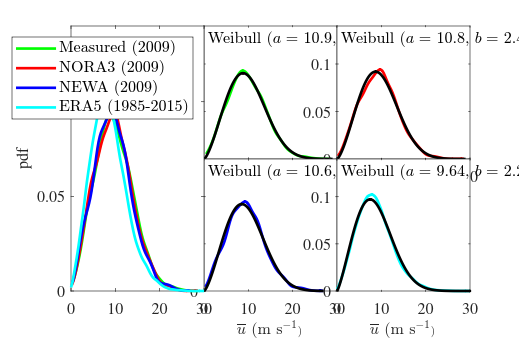

zTarget = 100;
plotFig3(BSH,NORA3,NEWA,ERA5,zTarget);

## Compare pdf of wind direction

This function is used to visualize the pdf of the wind direction at 62 m asl and 91 m asl for the year 2009 at the FINO1 platform. This visualization  compares:

- In-situ measurements from the FINO1 platform.

- Modeled data from NORA3 and NEWA.

- The ERA5 dataset's direction data for the period 1985-2015 at 100 m asl is also depicted, ensuring a comprehensive presentation.

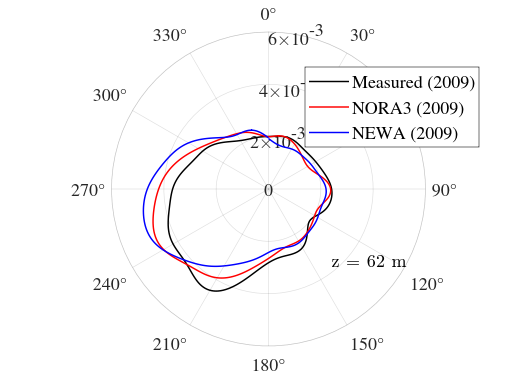

 circular distance between BSH and NORA3 is -4.66 
 circular distance between BSH and NEWA is -6.19 


zTarget = 62;
 plotFig4(BSH,NORA3,NEWA,ERA5,zTarget)

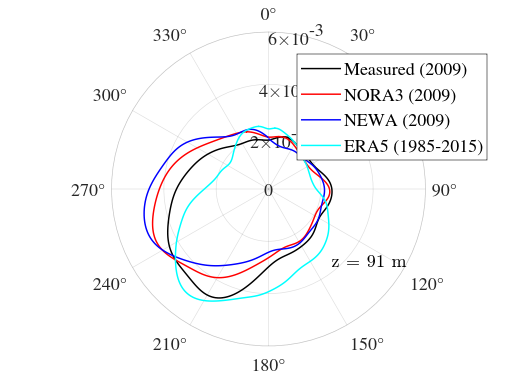

 circular distance between BSH and NORA3 is -8.66 
 circular distance between BSH and NEWA is -10.12 



zTarget = 91;
 plotFig4(BSH,NORA3,NEWA,ERA5,zTarget)

## Distribution of atmospheric static stability

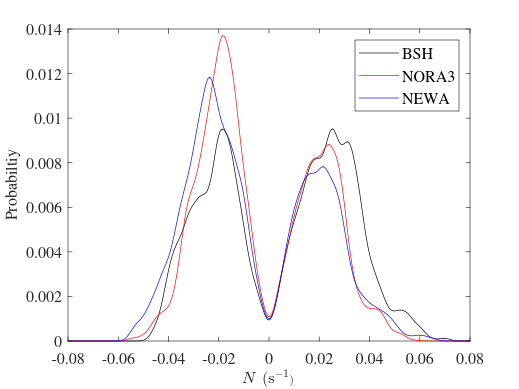

 load('./data/SST_FINO1_2009.mat','SST*','time')

zTarget = 101;

plotFig6(BSH,NORA3,NEWA,SST_GHRSST,SST_BSH,zTarget)

## Sea surface temperature comparison

The SST called SST_GHRSSTD is taken from [1]. See [https://www.ghrsst.org/](https://www.ghrsst.org/) for additional information

[1] [https://se.mathworks.com/matlabcentral/fileexchange/87222-automated-importation-of-sea-surface-temperature-data](https://se.mathworks.com/matlabcentral/fileexchange/87222-automated-importation-of-sea-surface-temperature-data)  

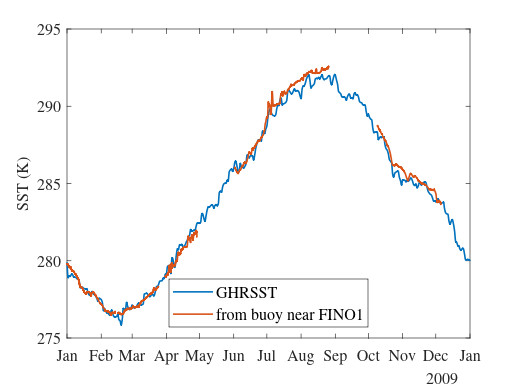

figure
plot(time,SST_GHRSST,time,SST_BSH,'linewidth',1.2)
set(gcf,'color','w')
ylabel('SST (K)')
legend('GHRSST','from buoy near FINO1','location','south')
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')